Impedance control characterization based on $x_e(t)$, $\dot{x}_e(t)$ and $f(t)$, for a 2º Order model with sinusoidal input.

close all
clear 
clc
% A = position error (deviation) input amplitude
% w_u = position error input frequency (angular)
syms s t A w_u K D M
% Matlab assumptions simplifies the computation and avoid complex numbers
assume([t A w_u K D M], {'real','positive'})
Es = A * w_u/(s^2 + w_u^2);
Fs = (M*s^2 + D*s + K)*Es

$$Fs = \frac{A\,w_{u}\,\left(M\,s^{2}+\text{D}\,s+K\right)}{s^{2}+{w_{u}}^{2}}$$

Et = ilaplace(Es)

$$Et = A\,\sin\left(t\,w_{u}\right)$$

dEt = ilaplace(s*Es);
Ft = ilaplace(Fs)

$$Ft = A\,K\,\sin\left(t\,w_{u}\right)+A\,\text{D}\,w_{u}\,\cos\left(t\,w_{u}\right)-A\,M\,{w_{u}}^{2}\,\sin\left(t\,w_{u}\right)$$

f_expr = latex(simplify(Ft));

## Parametric curve (ellipse) {x_e, dx_e, f_ref} 

% Stewart, Calculus: Early Transcendentals, 6ed, Chapter 13, Sub "The Normal and and Binormal Vectors"
C = [Et, dEt, Ft]; % Target curve
dC = simplify(diff(C,t));
T = dC; % Tangent vector
dT = simplify(diff(T,t));                    
Nn = dT; % Normal vector
B = simplify(cross(T,Nn)) % Binormal vector

$$B = \left(\begin{array}{ccc} A^{2}\,{w_{u}}^{4}\,\left(K-M\,{w_{u}}^{2}\right) & A^{2}\,\text{D}\,{w_{u}}^{4} & -A^{2}\,{w_{u}}^{4} \end{array}\right)$$

Then, the normal vector can be simply defined as:

b_vec = B*(1/(A^2*w_u^4)) % B was multiplied by 1/(A^2*w_u^4), keeping the orientation

$$b\_vec = \left(\begin{array}{ccc} K-M\,{w_{u}}^{2} & \text{D} & -1 \end{array}\right)$$

b_expr = latex(B);

% Considering Tx, and Ty sequential rotations:
tht = simplify(atan(-b_vec(2)/b_vec(3)),'Steps',1000) % minus due to right hand rule

$$tht = \mathrm{atan}\left(\text{D}\right)$$

phi = simplify(asin(-b_vec(1)/norm(b_vec)),'Steps',1000)

$$phi = -\mathrm{asin}\left(\frac{K-M\,{w_{u}}^{2}}{\sqrt{{\left(K-M\,{w_{u}}^{2}\right)}^{2}+{\text{D}}^{2}+1}}\right)$$

Tx  = simplify([1 0 0; 0 cos(tht) -sin(tht); 0 sin(tht) cos(tht)],'Steps',1000);
Ty  = simplify([cos(phi) 0 sin(phi); 0 1 0; -sin(phi) 0 cos(phi)],'Steps',1000);

% express the ellipse projection without the 'Tz':
Projection = (Tx*Ty)' * [Et dEt Ft]'; %(Tx*Ty)' = Ty'*Tx' --> Matrix properties

% explicit the cos(t*w_u), and sin(t*w_u) coefficients:
Projection = simplify(collect(Projection, [cos(t*w_u) sin(t*w_u)]),'Steps',1000);

% extract the Projection terms on the x and y axes only (1,2) as functions of cosine and sine
R(1,1) = subs(Projection(1,1), [cos(w_u*t) sin(w_u*t)], [0 1]); % assuming sin = 1 and cos = 0 we get the sin coeff.
R(1,2) = subs(Projection(1,1), [cos(w_u*t) sin(w_u*t)], [1 0]); % assuming sin = 0 and cos = 1 we get the cos coeff.
R(2,1) = subs(Projection(2,1), [cos(w_u*t) sin(w_u*t)], [0 1]);
R(2,2) = subs(Projection(2,1), [cos(w_u*t) sin(w_u*t)], [1 0]);
R = simplify(R/A, 'Steps', 1000); % A is just scaling the matrix and we can remove it to assume the cos/ sin functions with amplitude A
Tz = [R [0 0]'; 0 0 1];

% Derive the root ellipse semiaxes:
Q = abs(det(R));
P = R(1,1)^2 + R(2,1)^2 + R(1,2)^2 + R(2,2)^2;
Q = simplify(Q, 'Steps', 1000);
P = simplify(P, 'Steps', 1000);
a_x = simplify( 1/2*(sqrt(P + 2*Q) + sqrt(P - 2*Q)) , 'Steps', 1000);
b_x = simplify( 1/2*(sqrt(P + 2*Q) - sqrt(P - 2*Q)) , 'Steps', 1000);

## Plotting

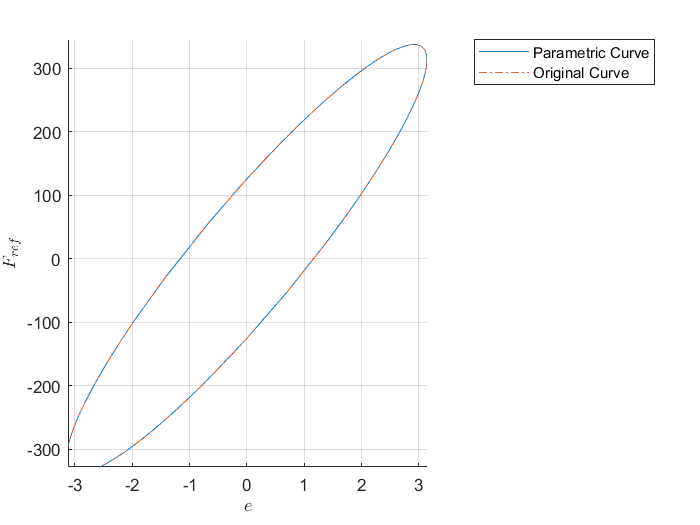

A0  = 3.14;
val_freq = 1/pi;      % => 2 rad/s
val_wu = 2*pi*val_freq;
Kd = 100; Dd = 2*sqrt(Kd); Md = .1;

T = double(subs(Tx*Ty*Tz, [w_u K D M], [val_wu Kd Dd Md]));

X = A0 * T * [cos(val_wu*t), sin(val_wu*t), 0]';
fplot3(X(1), X(2), X(3), [0 1/val_freq])
hold on
E  = subs(Et, [A w_u], [A0, val_wu]);
dE = subs(dEt, [A w_u], [A0, val_wu]);
F = subs(Ft, [A w_u K D M],  [A0 val_wu Kd Dd Md]);
fplot3(E, dE, F, [0 1/val_freq],'-.')
xlabel('$e$',"Interpreter","latex")
ylabel('$\dot{e}$',"Interpreter","latex")
zlabel('$F_{ref}$',"Interpreter","latex")
legend('Parametric Curve','Original Curve')
view(0,0)
hold off

% --- %

Inspecting the curve according to the parameters:

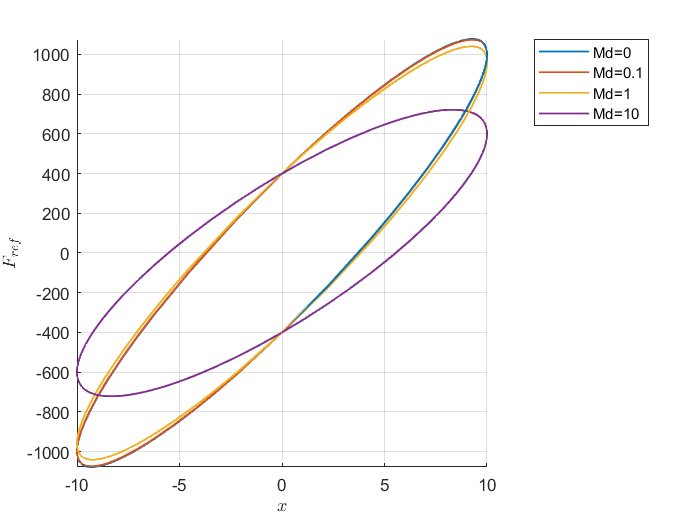

% Varying M
tA0  = 0.1;
val_freq = 0.31831;      % => 2 rad/s
val_wu = 2*pi*val_freq;
Kd = 100; Dd = 2*sqrt(Kd);
md_array = [0 0.1 1 10];
figure
for Md = md_array
    T = double( subs(Tx*Ty*Tz, [w_u K D M], [val_wu Kd Dd Md]));

    X = A0 * T * [cos(val_wu*t), sin(val_wu*t), 0]';
    fplot3(X(1), X(2), X(3), [0 1/val_freq], 'LineWidth', 1.0, ...
           'DisplayName', strcat('Md= ', num2str(Md)))
    hold on
end

xlabel('$x$',"Interpreter","latex")
ylabel('$\dot{x}$',"Interpreter","latex")
zlabel('$F_{ref}$',"Interpreter","latex")
legend('show')
view(0,0)
hold off